# Task No. 1b "Robot Arm"

The final transfer function of the arm is given by:

clear;
clc;

s = tf('s');
G = (8*(s + 2))/(s*(s - 5)*(s - 2));

## 1. Find the poles , zeros and characteristic equation of the system.

% Poles of system
p = pole(G)

p =      0
     5
     2


% Zeros of system
z = zero(G)

z = -2

% The characteristic equation 
Gch = (8*s + 16)/(s^3 - 7*s^2 + 10*s)

Gch =
 
       8 s + 16
  ------------------
  s^3 - 7 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


## **2. Is the system stable or not. Justify.**

*The poles of the TF are positiv real values thus the system being unstable. For further proof the 'isstable()' function of MATLAB can be used.*

isstable(G)

ans = logical
   0


## **3. Find the equations of state from the transfer function and determine whether the system is Controllable and/or Observable.**

The TF of the system is as already stated:


$$G\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=\frac{8s+16}{s^3 -7s^2 +10s}$$


To decouple the numerator and denominator terms following equations can be formed:


$$\begin{array}{l}
\frac{X\left(s\right)}{U\left(s\right)}=\frac{1}{s^3 -7s^2 +10s},\\
\frac{Y\left(s\right)}{X\left(s\right)}=8s+16
\end{array}$$


To derive the state matrix $A$ and the input matrix $B$ the inverse Laplace-transform of the denominator term is performed.


$$X\left(s\right)\left(s^3 -7s^2 +10s\right)=U\left(s\right)\to \dddot{\;x\;} =7\ddot{\;x\;} -10\dot{\;x\;} +u$$


The state and the state derivative vector are as follows:


$$\bar{x\;} =\left\lbrack \begin{array}{c}
x=x_1 \\
\dot{\;x\;} =x_2 \\
\ddot{\;x\;} =x_3 
\end{array}\right\rbrack \to \bar{\dot{x} } =\left\lbrack \begin{array}{c}
\dot{\;x_1 } =\dot{\;x\;} \\
\dot{\;x_2 } =\ddot{\;x\;} \\
\dot{\;x_3 } =\dddot{\;x\;} 
\end{array}\right\rbrack$$


Thus the state matrix $A$ and input matrix $B$ is as follows:


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -10 & 7
\end{array}\right\rbrack ,B=\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$


A = [0 1 0; 0 0 1; 0 -10 7];
B = [0; 0; 1];

The inverse Laplace-transform is as follow:


$$y=8\dot{\;x} +16x$$


Thus the output matrix $C$ and the feedtrough matrix $D$ is as follow:


$$C=\left\lbrack \begin{array}{ccc}
16 & 8 & 0
\end{array}\right\rbrack$$


C = [16 8 0];
D = 0;

To check the controllability of the system the 'ctrb' command of MATLAB can be used.

Ctrl = ctrb(A,B)

Ctrl =      0     0     1
     0     1     7
     1     7    39


The rank of the controllability matrix tells if the system is controllable or not. If the value of the rank is equal the number of the states, than the system is controllable.

rank_Ctrl = rank(Ctrl)

rank_Ctrl = 3

To calculate the observability matrix the MATLAB command 'obsv' can be used. The rank of the observability matrix tells us agains if the system is observable or not.

Obsv = obsv(A,C)

Obsv =     16     8     0
     0    16     8
     0   -80    72


rank_Obsv = rank(Obsv)

rank_Obsv = 3

## 4. Calculate the roots of the closed system with unitary feedback.

To find the closed loop transfer function of the system following calculation will be performed:


$$G_{\textrm{cl}} \left(s\right)=\frac{G\left(s\right)}{1+G\left(s\right)}=\frac{8s+16}{s^3 -7s^2 +18s+16}$$


To get a stationary value of 1 with an input 1 the inverse of the numerator is multiplied with transfer function.

Gcl = (8*s + 16)/(s^3 - 7*s^2 + 18*s + 16) * 1/(8*s + 16)

Gcl =
 
                8 s + 16
  -------------------------------------
  8 s^4 - 40 s^3 + 32 s^2 + 416 s + 256
 
Continuous-time transfer function.
Model Properties


Roots in system theory is the same thing as zeros, thus with the MATLAB command 'zero' the zeros can be determined:

zero(Gcl)

ans = -2

## 5. Plot the response of the system to a step input.

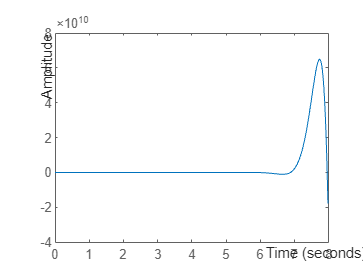

step(Gcl)

## 6. Find the parameters of a suitable PID controller for the above system.

### Parameters : below 22% overshoot and below 12 sec settling time.

% Define PID parameters
KP = 7;
KI = 0;
KD = 5;

% Define closed loop pid system
Gctr = pid(KP,KI,KD)

Gctr =
 
             
  Kp + Kd * s
             

  with Kp = 7, Kd = 5
 
Continuous-time PD controller in parallel form.
Model Properties


GPID = feedback(Gctr*Gch,1)

GPID =
 
     40 s^2 + 136 s + 112
  --------------------------
  s^3 + 33 s^2 + 146 s + 112
 
Continuous-time transfer function.
Model Properties


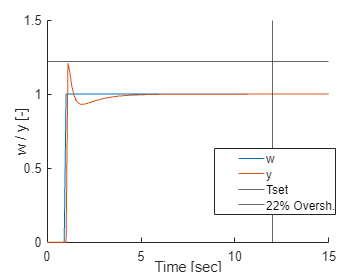


% Define time and reference array
t = (0:0.1:15)';
w = zeros(length(t),1);
w(find(t == 1):end) = 1;

% Simulate system
y = lsim(GPID,w,t);

% Plot results
figure
hold on
plot(t,w,'DisplayName','w')
plot(t,y,'DisplayName','y')
xline(12,'DisplayName','Tset')
yline(1.22,'DisplayName','22% Oversh.')
ylim([0 1.5])
xlabel('Time [sec]')
ylabel('w / y [-]')
legend

xlim([0.0 15.0])
ylim([0.00 1.50])
legend("Position", [0.59186,0.21126,0.33333,0.24081])

## 7. Find a feedback matrix K such that the closed system has poles with the values −120 and (−7 + 2i) , (−7 − 2i).

The matrix K can be determined by pole placement. MATLAB includes the command 'place' in which this process can be done.

% Desired poles
p_des = [-120, -7 + 2*1i, -7 - 2*1i]

p_des = 1.0e+02 *

  -1.2000 + 0.0000i  -0.0700 + 0.0200i  -0.0700 - 0.0200i



% Pole placement
K = place(A,B,p_des)

K = 1.0e+03 *

    6.3600    1.7230    0.1410


To get stationary accuracy following matrix M has to be calculated:

y_SS = lsim(ss((A - B*K),B,C,D),w,t);
M = y_SS(end);
% M = 1/dcgain(ss(A,B,C,D))